# Unsupervised Learning In-Class Practice: Answer Key

## Loading and examining the data

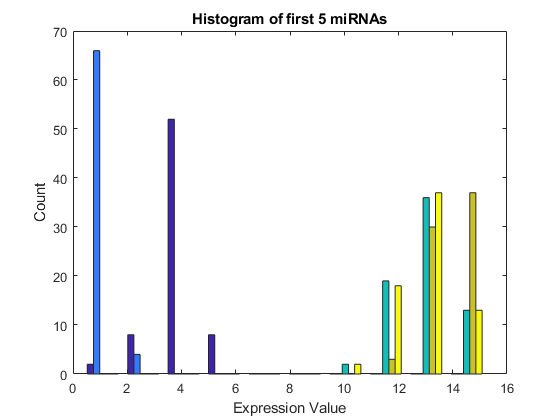

% Load the dataset
miRNA = readtable('miRNA_data.xlsx');
% Create a variable for patient IDs
patient_ID = miRNA.Patient_ID;
% Create a variable for patient health status
health_stat = miRNA.Health_Status; 
% Create a variable for miRNA names
miRNA_names = miRNA.Properties.VariableNames(3:end);
% Create a variable for miRNA expression data
miRNA_data = table2array(miRNA(:,3:end));

% Histogram of miRNA expression data
figure
hist(miRNA_data(:,1:5))
xlabel('Expression Value'); ylabel('Count')
title('Histogram of first 5 miRNAs')

Answer: The expression level for two miRNAs is much lower that the other three. In other words, the distribution of expression level for different miRNAs within this dataset may be drastically different. 

## Determining optimal k value using KMC

% Demo for k-means clustering                                 
idx = kmeans(miRNA_data,2);             % identify clusters with k-means clustering
s = silhouette(miRNA_data,idx);         % determine silhouette values 
s_score = mean(s)                       % calculate silhouette score 

s_score = 0.5539

% Create a vector of k values ranging from 2 to 10
k_values = 2:10;

% For-loop to calculate the silhouette statistic for different k values
n = length(k_values);       % number of k values
s_score = zeros(n,1);       % variable to store silhouette statistic values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    idx = kmeans(miRNA_data,k_values(i));
    % Use the silhouette function to determine silhouette values
    s = silhouette(miRNA_data,idx);
    % Calculate the silhouette score by taking the mean
    s_score(i) = mean(s);
end
table(k_values',s_score)

ans = 9×2 table
    Var1    s_score
    ____    _______
      2     0.55386
      3     0.38498
      4     0.37573
      5     0.27448
      6     0.25316
      7     0.24106
      8     0.19102
      9      0.2426
     10      0.2087

k = find(s_score==max(s_score))+1

k = 2

Answer: The max silhouette statistic is equal to 0.5539, and this corresponds with k = 2.

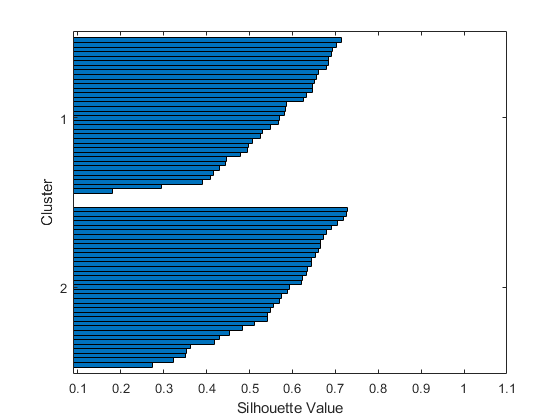

% Silhouette plot based on best k value
idx = kmeans(miRNA_data,k);
silhouette(miRNA_data,idx)

Answer: No negative values are present, but a negative silhouette value would imply that its associated observation was not well-placed into its assigned cluster. 

cluster_1 = health_stat(idx == 1)

cluster_1 = 35×1 cell array
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'diseased'}
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }

cluster_2 = health_stat(idx == 2)

cluster_2 = 35×1 cell array
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}

Answer: The patients cluster based on health status (for the most part).

## Visualizing data in lower dimension using PCA

% Do PCA (determine PC matrix, transformed data matrix, and variance explained)
[P, Y, ~, ~, explained] = pca(miRNA_data)

P =     0.0300    0.1534    0.3029    0.1504    0.0663    0.1182   -0.4002   -0.0045    0.5085   -0.3034    0.1787   -0.1735   -0.1140    0.2350    0.4104   -0.1825   -0.0005    0.0013
    0.0240   -0.0108    0.0908    0.0733    0.0956   -0.0254    0.2192    0.1598    0.1677    0.0560    0.5612    0.7410   -0.0274   -0.0606    0.0497    0.0104    0.0065    0.0039
   -0.2578   -0.0717    0.1162    0.1293   -0.0636    0.1584   -0.0709   -0.0355   -0.1661   -0.0199    0.0689    0.0105   -0.0862   -0.0701   -0.1670   -0.3545    0.7997   -0.1566
   -0.2587   -0.0726    0.1167    0.1277   -0.0606    0.1605   -0.0716   -0.0386   -0.1648   -0.0197    0.0687    0.0144   -0.0848   -0.0777   -0.1627   -0.3446   -0.2639    0.7754
   -0.2564   -0.0736    0.1184    0.1276   -0.0624    0.1609   -0.0747   -0.0376   -0.1667   -0.0164    0.0726    0.0232   -0.0835   -0.0677   -0.1648   -0.3527   -0.5392   -0.6116
   -0.1416   -0.3361    0.0930    0.0046    0.0537    0.1778   -0.1483    0.2345   -0.4866 

Y =    -4.8206    1.8952    0.2486    0.3666   -0.3778   -0.9746   -0.2439   -0.0500   -0.4457   -0.4071   -0.3724    0.3820    0.5330    0.1353    0.3086   -0.1073   -0.0032   -0.0039
   -2.6433    0.3761    0.3641    1.1508   -1.7826    0.6302    0.3440   -0.1008   -0.0889   -0.0544   -0.2776    0.0622    0.0650   -0.2005    0.0950   -0.1640   -0.0004   -0.0000
   -2.9064    0.4478   -0.5345    0.8140   -0.8675   -0.9135   -0.0047    0.1337   -0.0489   -0.0825    0.2378   -0.2979   -0.5160    0.1645    0.0886    0.2755    0.0017   -0.0001
    4.7762    1.3941    0.2017   -3.8618    1.7310    0.2733   -0.0400   -1.1672    0.0177    0.2227   -0.1302    0.0329   -0.2356   -0.4422    0.1806    0.1585    0.0018    0.0020
    1.6909    0.0815   -0.2951    0.5706    1.0015    0.7312   -0.2389   -0.3995   -0.2371    1.0762   -0.6464    0.1469    0.3325    0.1882    0.3333   -0.1993   -0.0070   -0.0016
    3.8011    1.1033    0.3089    1.3176    0.5251   -1.1256   -0.4901   -0.4099   -0.1381 

explained =    46.9119
   15.7222
   10.7405
    7.2704
    5.5997
    3.6613
    2.0605
    1.7339
    1.5851
    1.3276


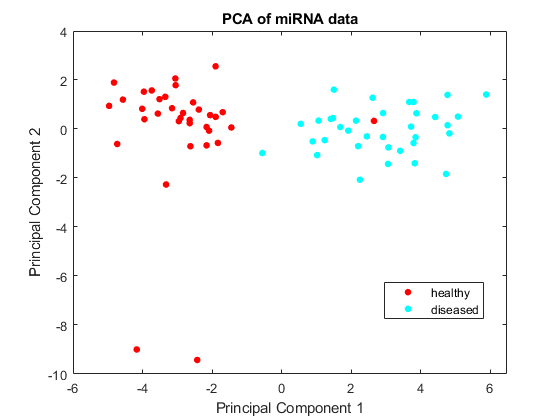

% Visualize transformed data on PC1 vs. PC2 plot (label = patient health status)
figure
gscatter(Y(:,1), Y(:,2), health_stat)
xlabel('Principal Component 1')
ylabel('Principal Component 2')
title('PCA of miRNA data')

Answer: There seems to be two distinct clusters with two outliers. PC1 and PC2 account for 62.6% of the variance.

Answer: Yes, it seems like the clusters we see from PCA match with our results from k-means clustering if we separate the data along PC1.

% Create table of genes matched to coefficients of best PC
PC1 = P(:,1); 
table(miRNA_names',PC1)

ans = 18×2 table
          Var1             PC1   
    ________________    _________
    {'hsa_let_7f_1'}     0.030013
    {'hsa_mir_122' }     0.023985
    {'hsa_let_7a_1'}     -0.25779
    {'hsa_let_7a_2'}     -0.25868
    {'hsa_let_7a_3'}     -0.25639
    {'hsa_let_7b'  }     -0.14155
    {'hsa_let_7c'  }     -0.30004
    {'hsa_let_7d'  }    0.0069857
    {'hsa_let_7e'  }     -0.22136
    {'hsa_let_7f_2'}     -0.28449
    {'hsa_let_7g'  }    0.0058268
    {'hsa_let_7i'  }     0.078598
    {'hsa_mir_10b' }      0.10396
    {'hsa_mir_145' }    -0.085872
    {'hsa_mir_155' }      0.29161
    {'hsa_mir_21'  }      0.35256

Answer: miRNA 33a has the greatest weight (0.4131) for PC1.

## Identifying differentially expressed miRNAs using HC

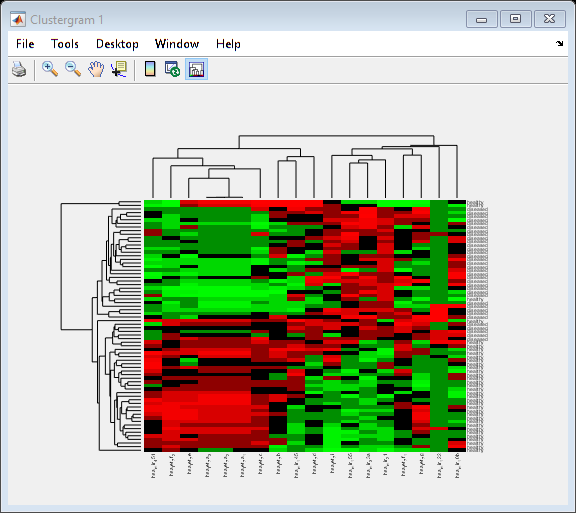

% Create clustergram (label rows, label columns, and standardize by columns)
miRNA_cg = clustergram(miRNA_data,...
    'RowLabels',health_stat,...
    'ColumnLabels',miRNA_names,...
    'Standardize','column');

Answer: It seems that the outliers were picked out at the edges, but the two clusters we've seen before are not clearly separated. 

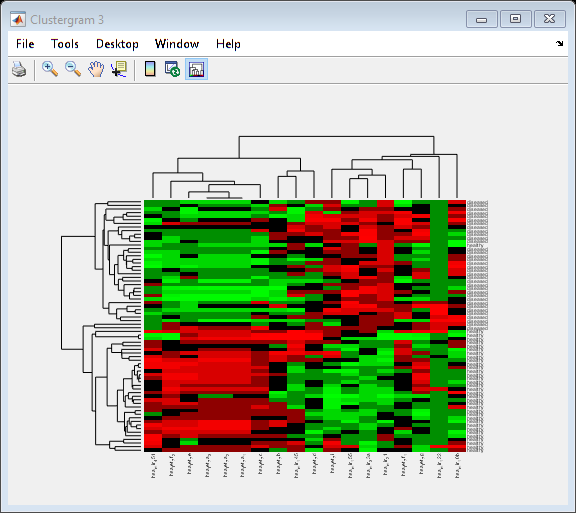

% Create clustergram (label rows, label columns, standardize by columns
% and use correlation as distance metric for rows and columns)
miRNA_cg_corr_rbc = clustergram(miRNA_data,...
    'RowLabels',health_stat,...
    'ColumnLabels',miRNA_names,...
    'Standardize','column',...
    'RowPDist','correlation',...
    'ColumnPDist','correlation');

Answer: As opposed to before, this clustergram better separates patients according to their health status. This matches closer to our previous results from KMC and PCA. 

Answer: Based on the clustergram, the following miRNAs appear to be differentially expressed between healthy and diseased individuals: miR-451, *Let*-7, miR-155, miR-33, and miR-21. 